# Exercise: Multidomain hydraulic-mechanical system

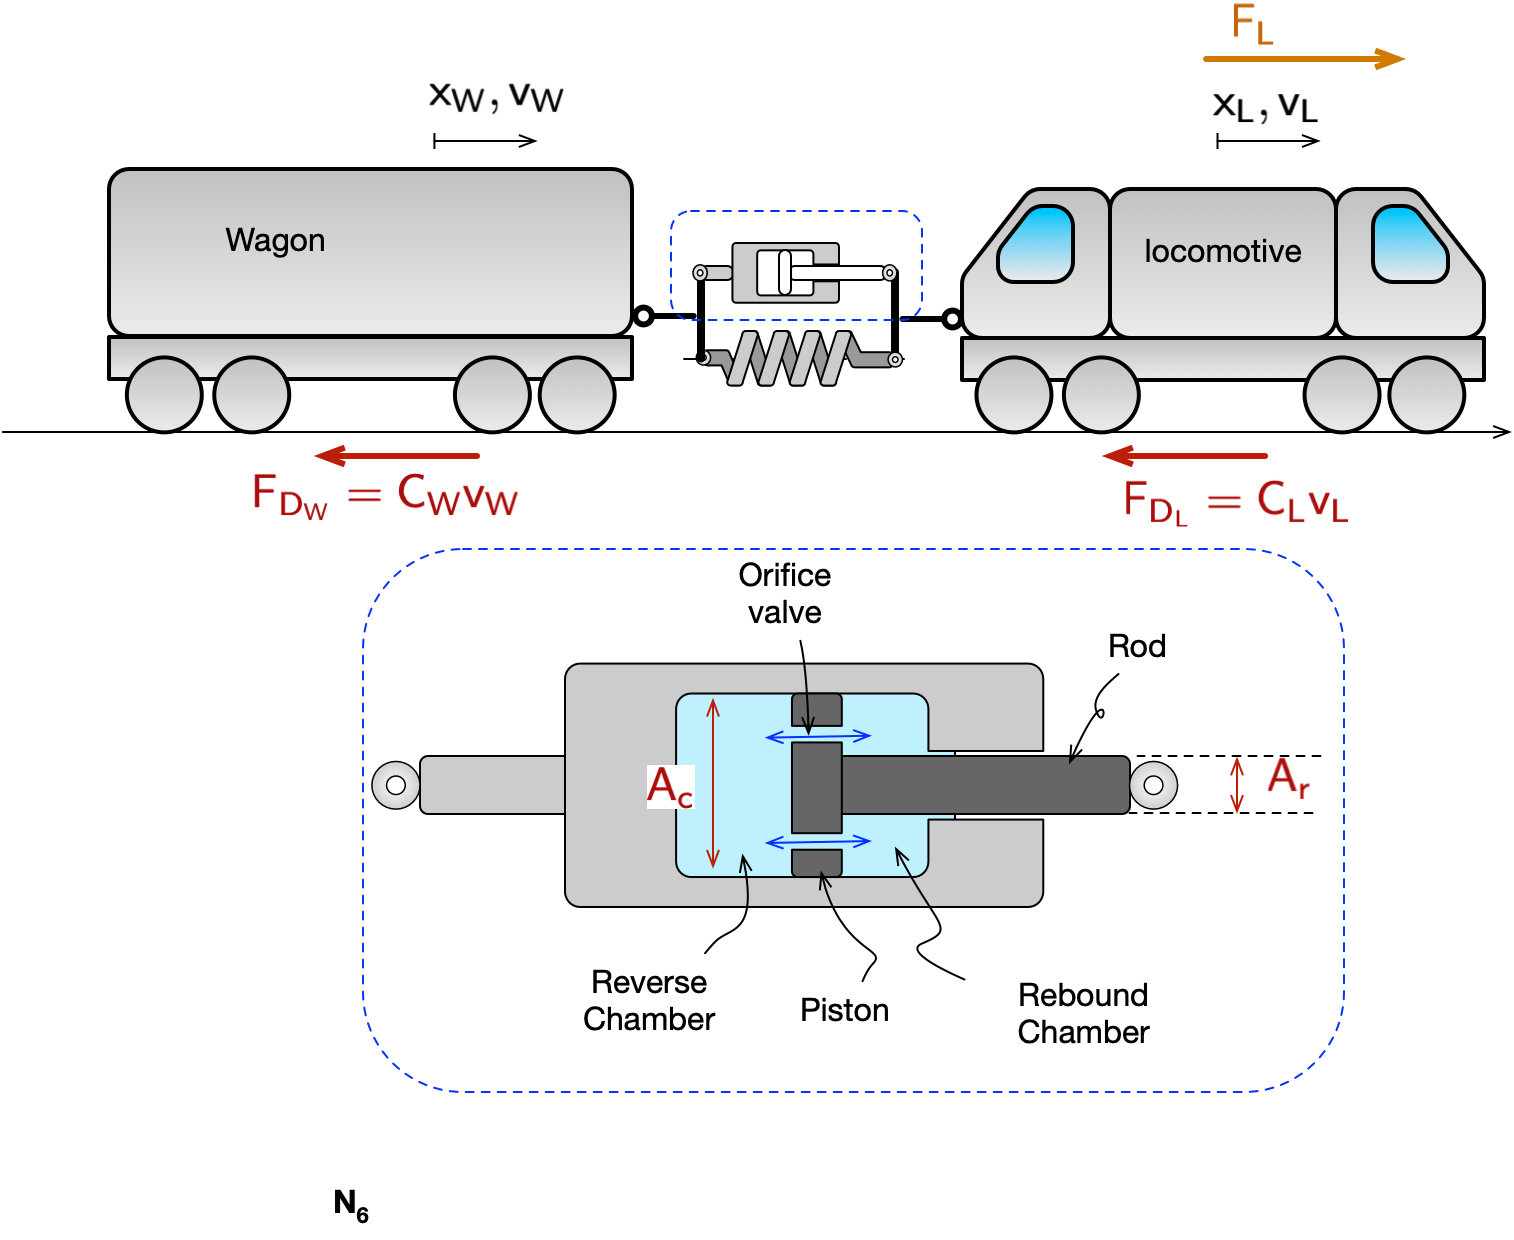

The system has the following components

- The locomotive and wagon masses which are an A-type elements (1 edge)

- The spring is a T-type element  (1 edge)

- The double piston coupler (2 edges )

- Two dampers that models the rolling friction  which are D-type element(1 edges )

- The resistor is a D-type element (1 edge)

- The force source is an T-type source (1 edge)

**In total we have 11 edges thus 11 constitutive equations**

## **Explanation of damper modelling**

**The system is modeled with a double piston transformer where the pressure is the pressure difference between the two cambers and the flow Q is the difference between the flow IN minus the flow OUT.**

**Please note that it can work only if the rod cross section **$ A_{c2} = A_{c1} -A_r$ **is negligible and **$A_{c1} = A_{c2}$. 

In fact, the volume of fluid leaving the first camber is entering instantaneously in the second chamber. However, the total volume of the two chambers does not change.


$$V_0 = V_{c1}+V_{c2} \rightarrow V_0 = A_{c1} x(t) +A_{c2}\left(L-x(t)\right) \overset{\frac{d}{d t}}{\longrightarrow} 0 = A_{c1} v(t) -A_{c2} v(t) \Rightarrow \left(A_{c1}  -A_{c2} \right)v(t) = 0 $$


This equation can be satisfied only if $A_{c1} = A_{c2}$ other wise the $v(t) =0$ not to violate the continuity equation.

Only if the damper moves very slowly we can assume the continuity equation is satisfied. Otherwise the difference of flow, which is $A_r v(t)$ must be accumulated somewhere in the damper.

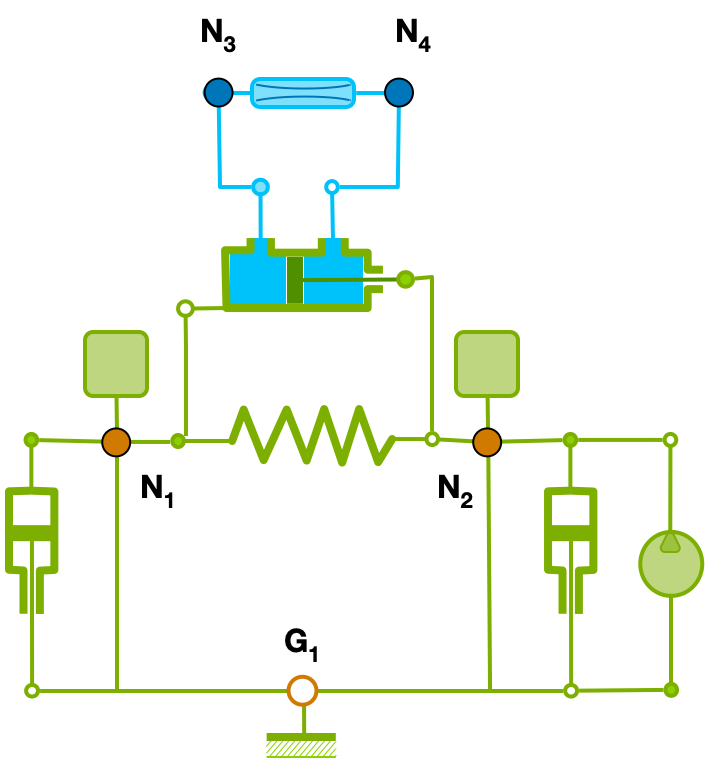

## Linear graph and normal tree

System Graph with the normal tree is shown in the picture In blue the hydraulic branch in green the mechanical branch. 

The two couplers (i.e the pistons) are shown also with the dashed squares that present the connection between the two domains.

Please note that, for convenience of representation of the linear graph, the ground node G1 has been split in three but it must be considered as one in the graph.

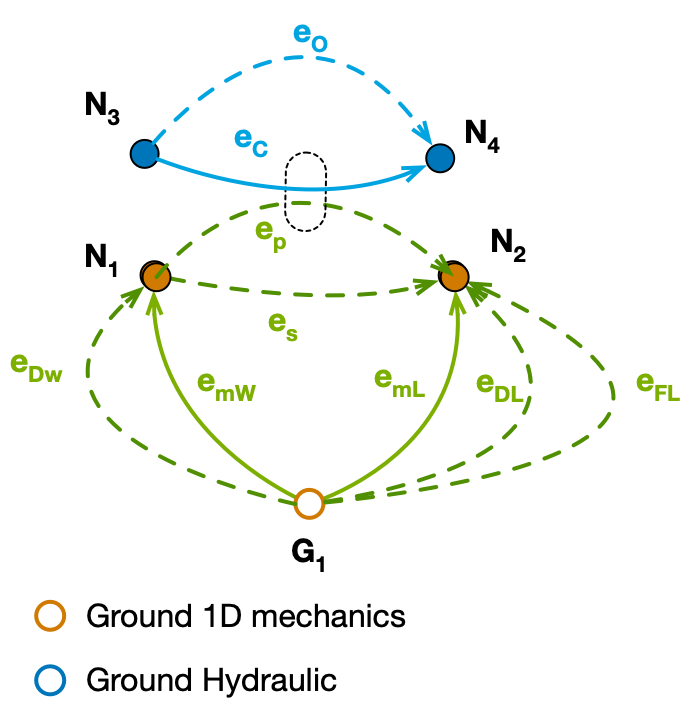

## Definitions

Definition of across and through variables

clc
clear 
close all
%
% library folder to use the utility functions
addpath('MBlibs')

Definition of problem variables

syms t

N = 9; % Number of edges 

% alpha_vars = sym("alpha_%d",[N,0]);
% tau_vars = sym("tau_%d",[N,0]);
% alpha_vars = sym.empty(1,0);
% tau_vars = sym.empty(1,0);
% % number of functions
% for k = 1:N
%     eval(sprintf('syms tau%d(t)', k));
%     eval(sprintf('syms alpha%d(t)', k));
%     % Optionally initialize a value: eval(sprintf('alpha%d(t) = 0;', k));
%     % Build a row vector of the symbolic functions evaluated at t
%      alpha_vars(k) = str2sym(sprintf('alpha%d(t)', k));
%     tau_vars(k) = str2sym(sprintf('tau%d(t)', k));
% end
% 
% tau_vars = tau_vars.';
% alpha_vars = alpha_vars.';

syms t v_s(t) v_mW(t) v_mL(t) v_DW(t) v_DL(t) v_FL(t) v_p(t) p_c(t) p_O(t)
syms t F_s(t) F_mW(t) F_mL(t) F_DW(t) F_DL(t) F_FL(t) F_p(t) Q_c(t) Q_O(t)  

% NOTE: The order of the variable on the vector MUST match the order in the IM
%              emL      emW    ec     ep    eDW      eDL     eO     eS     eFL
tau_vars   = [F_mL(t) F_mW(t) Q_c(t) F_p(t) F_DW(t) F_DL(t) Q_O(t) F_s(t) F_FL(t)].';
alpha_vars = [v_mL(t) v_mW(t) p_c(t) v_p(t) v_DW(t) v_DL(t) p_O(t) v_s(t) v_FL(t) ].';

length(tau_vars) == length(alpha_vars)

ans = logical
   1


## Constitutive equations

We define the constitutive equations for each element (i.e. edge)

% A_c*p1-A_c*p0 ==

% we add an extra variable which is the spring displacement and one
% additional constitutive equations

syms F_L0 m_L m_W K_s C_DW C_DL A_c A_r R

eqns_const = [ % mass locomotive
               diff(v_mL(t),t) == 1/m_L*F_mL(t)
               % mass wagon
               diff(v_mW(t),t) == 1/m_W*F_mW(t)
               % spring: defined as differential being v_s a velocity
               diff(F_s(t),t) == K_s*v_s(t)
               % Force source
               F_FL(t) == F_L0
               % rolling friction on wagon 
               F_DW(t) == C_DW*v_mW(t)
               % rolling friction on locomotive 
               F_DL(t) == C_DL*v_mL(t)
               % double-piston coupler
               F_p(t) == A_c*p_c(t)
               Q_c(t) == A_c*v_p(t)
               % resistor
               p_O(t)  == R*Q_O(t) 
              ]

$$eqns\_const = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=\frac{F_{\mathrm{mL}}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{\mathrm{mW}}\left(t\right)}{m_{W}}\\ \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,v_{s}\left(t\right)\\ F_{\mathrm{FL}}\left(t\right)=F_{\mathrm{L0}}\\ F_{\mathrm{DW}}\left(t\right)=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)\\ F_{\mathrm{DL}}\left(t\right)=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)\\ F_{p}\left(t\right)=A_{c}\,p_{c}\left(t\right)\\ Q_{c}\left(t\right)=A_{c}\,v_{p}\left(t\right)\\ p_{O}\left(t\right)=R\,Q_{O}\left(t\right) \end{array}\right)$$

length(eqns_const)

ans = 9

## Loop and node equations

### Incidence matrix

The incidence matrix has tow singular row in this cases. We write directly the matrix without singular rows.

%      emL emW ec  ep eDW eDL  eO   eS  eFL   
IM = [ 0    1   0  -1  1   0    0   -1   0 ;   % N1
       1    0   0   1  0   1    0    1   1 ;   % N2
%       0    0  -1   0  0   0   -1    0   0 ;   % N3
       0    0   1   0  0   0    1    0   0 ;   % N4
      -1   -1   0   0 -1  -1    0    0  -1 ;   % G1
       0    0  -1   0  0   0   -1    0   0 ;   % G2 = N3
     ]

IM =      0     1     0    -1     1     0     0    -1     0
     1     0     0     1     0     1     0     1     1
     0     0     1     0     0     0     1     0     0
    -1    -1     0     0    -1    -1     0     0    -1
     0     0    -1     0     0     0    -1     0     0


[nn,ne] = size(IM);

% Check system consistency
if ~(length(alpha_vars) == ne )
  error 'Inconsistent dimensions'
end
% row reduced Echelon Form.
rref(IM)

ans =      1     0     0     1     0     1     0     1     1
     0     1     0    -1     1     0     0    -1     0
     0     0     1     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


Two rows are lineraly dependent since they correspond to the ground

rank(IM)

ans = 3

%IM*tau_vars
% Number of elements, number of branches and number of chords
% Reduced Incidence Matrix
nb = nn-2;  % n_nodes-1
ne ;        % number of edges
nc = ne-nb; % number of chords
%reduced IM: ground node is deleted

A = sym(IM(1:nb,1:ne))

$$A = \left(\begin{array}{ccccccccc} 0 & 1 & 0 & -1 & 1 & 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 1 & 0 & 1 & 0 & 1 & 1\\ 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

% compute Af matrix: Af = [Ib | Ac]
Af = rref(A)

$$Af = \left(\begin{array}{ccccccccc} 1 & 0 & 0 & 1 & 0 & 1 & 0 & 1 & 1\\ 0 & 1 & 0 & -1 & 1 & 0 & 0 & -1 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

Ac = Af(:,nb+1:end)  % Ac = Af(1:nb,nb+1:ne);

$$Ac = \left(\begin{array}{cccccc} 1 & 0 & 1 & 0 & 1 & 1\\ -1 & 1 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

### Node equations (i.e. Newton Equations at nodes)

Node equations are derived from the rows of rowEchelon form of the reduced incidence matrix: they are the **fundamental cutsets  **$\mathbf{A}_f = [\mathbf{I}_b | \mathbf{A}_C] $.

node_eqns = tau_vars(1:nb)==-Ac*tau_vars(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)=-F_{\mathrm{DL}}\left(t\right)-F_{\mathrm{FL}}\left(t\right)-F_{p}\left(t\right)-F_{s}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)=F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)\\ Q_{c}\left(t\right)=-Q_{O}\left(t\right) \end{array}\right)$$

### Circuits equations/Loop equations

We find the **fundamental circuits** from the Af matrix. The Bf matrix which is the circuit loop matrix is derived as null space of matrix Af. $\mathbf{B}_f = [ \mathbf{B}_b | \mathbf{I}_c] $

Bf = null(Af).'

$$Bf = \left(\begin{array}{ccccccccc} -1 & 1 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ -1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 1 & 0 & 0\\ -1 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Af*Bf'

$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

We compute the Bb matrix explointing the principle of 

Bb = -Ac'

$$Bb = \left(\begin{array}{ccc} -1 & 1 & 0\\ 0 & -1 & 0\\ -1 & 0 & 0\\ 0 & 0 & -1\\ -1 & 1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

Ic = Bf(:,nc+1:ne)

$$Ic = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

#### Loop equations

% Bb = Bf(:,1:nb)
% Ic = Bf(:,nc:ne)

Branch across variables as function of across chords variables

loop_eqns = alpha_vars(nb+1:ne)==-Bb*alpha_vars(1:nb) 

$$loop\_eqns = \left(\begin{array}{c} v_{p}\left(t\right)=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{DW}}\left(t\right)=v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{DL}}\left(t\right)=v_{\mathrm{mL}}\left(t\right)\\ p_{O}\left(t\right)=p_{c}\left(t\right)\\ v_{s}\left(t\right)=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{FL}}\left(t\right)=v_{\mathrm{mL}}\left(t\right) \end{array}\right)$$

## DAE system of equations 

### Dependent and independent coordinates

The **dependent variables** are the set of **chord across coordinates** and of the **throught branch coordinates**:

% dependent set of equations from loop and node equations
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

$$qvars\_d = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)\\ Q_{c}\left(t\right)\\ v_{p}\left(t\right)\\ v_{\mathrm{DW}}\left(t\right)\\ v_{\mathrm{DL}}\left(t\right)\\ p_{O}\left(t\right)\\ v_{s}\left(t\right)\\ v_{\mathrm{FL}}\left(t\right) \end{array}\right)$$

% independent set of DAE variables
allvars = [alpha_vars;tau_vars;];
dae_vars = setdiff(allvars,qvars_d) % dae_vars

$$dae\_vars = \left(\begin{array}{c} F_{\mathrm{DL}}\left(t\right)\\ F_{\mathrm{DW}}\left(t\right)\\ F_{\mathrm{FL}}\left(t\right)\\ F_{p}\left(t\right)\\ F_{s}\left(t\right)\\ Q_{O}\left(t\right)\\ p_{c}\left(t\right)\\ v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right) \end{array}\right)$$

### Assembling and solving equations

% Substitute loop equantions into constitutive equations
%subs( eqns_const, sym2cell(lhs(eqns_loop)),sym2cell(rhs(eqns_loop)))
tmp = subs( eqns_const, lhs(loop_eqns),rhs(loop_eqns));
% substitute node equations
dae_eqns = subs( tmp, lhs(node_eqns), rhs(node_eqns))

$$dae\_eqns = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{\mathrm{DL}}\left(t\right)+F_{\mathrm{FL}}\left(t\right)+F_{p}\left(t\right)+F_{s}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)}{m_{W}}\\ \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,\sigma_{1}\\ F_{\mathrm{FL}}\left(t\right)=F_{\mathrm{L0}}\\ F_{\mathrm{DW}}\left(t\right)=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)\\ F_{\mathrm{DL}}\left(t\right)=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)\\ F_{p}\left(t\right)=A_{c}\,p_{c}\left(t\right)\\ -Q_{O}\left(t\right)=A_{c}\,\sigma_{1}\\ p_{c}\left(t\right)=R\,Q_{O}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

Check dimensions

if ~(length(qvars_d)==N)
  fprintf('dep. vars %d <> n. elements %d',length(qvars_d),N)
  error 'Inconsistent number of dependent variables'
end
if ~(length(eqns_const)==N)
  fprintf('n. constitutive eqns. %d <> n. elements %d',length(eqns_const),N);
  error 'Constitutive equations must be equal to number of dependent variables'
end
if ~(length(dae_eqns)==length(dae_vars))
  fprintf('n.dae eqns %d <> n. eqns vars %d',length(dae_eqns),length(dae_vars))
  error 'Inconsistent set of equations'
end

### Equations manipulation: index reduction

[E_mat, G_vec] = massMatrixForm(dae_eqns,dae_vars)

$$E\_mat = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G\_vec = \begin{array}{l} \left(\begin{array}{c} -\frac{F_{\mathrm{DL}}\left(t\right)+F_{\mathrm{FL}}\left(t\right)+F_{p}\left(t\right)+F_{s}\left(t\right)}{m_{L}}\\ \frac{F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)}{m_{W}}\\ K_{s}\,\sigma_{1}\\ F_{\mathrm{L0}}-F_{\mathrm{FL}}\left(t\right)\\ C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{DW}}\left(t\right)\\ C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{DL}}\left(t\right)\\ A_{c}\,p_{c}\left(t\right)-F_{p}\left(t\right)\\ Q_{O}\left(t\right)+A_{c}\,\sigma_{1}\\ R\,Q_{O}\left(t\right)-p_{c}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

Equations/Variables sorting

Use Dulmage-Mendelsohn algorithm to reorder the equations

[p,q,~,~,~,~] = dmperm(double(E_mat));
% Rebuilt sorted system
E_sorted = E_mat(p, :) % ONLY equations order is changed

$$E\_sorted = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sorted = G_vec(p) ;
% not full rank: system is dae
n_ode = rank(E_sorted)

n_ode = 3

dae_vars

$$dae\_vars = \left(\begin{array}{c} F_{\mathrm{DL}}\left(t\right)\\ F_{\mathrm{DW}}\left(t\right)\\ F_{\mathrm{FL}}\left(t\right)\\ F_{p}\left(t\right)\\ F_{s}\left(t\right)\\ Q_{O}\left(t\right)\\ p_{c}\left(t\right)\\ v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right) \end{array}\right)$$

%dae_vars_sorted = flip(dae_vars(q))
% Equations are reordered
eqns_sorted = E_sorted*diff(dae_vars,t)==G_sorted

$$eqns\_sorted = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,\sigma_{1}\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{\mathrm{DL}}\left(t\right)+F_{\mathrm{FL}}\left(t\right)+F_{p}\left(t\right)+F_{s}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)}{m_{W}}\\ 0=F_{\mathrm{L0}}-F_{\mathrm{FL}}\left(t\right)\\ 0=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{DW}}\left(t\right)\\ 0=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{DL}}\left(t\right)\\ 0=A_{c}\,p_{c}\left(t\right)-F_{p}\left(t\right)\\ 0=Q_{O}\left(t\right)+A_{c}\,\sigma_{1}\\ 0=R\,Q_{O}\left(t\right)-p_{c}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

We get the ode equations which are the firt `n_ode` equations

% Extract odes equations
ode_eqns = eqns_sorted(1:n_ode)

$$ode\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{\mathrm{DL}}\left(t\right)+F_{\mathrm{FL}}\left(t\right)+F_{p}\left(t\right)+F_{s}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)}{m_{W}} \end{array}\right)$$

Extract the differential variables from the ode equations

% Extract the vector of differential variables
ode_vars = get_ode_vars(dae_vars,ode_eqns)

$$ode\_vars = \left(\begin{array}{c} F_{s}\left(t\right)\\ v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right) \end{array}\right)$$

Now the remaining are the algebraic variables

% Extract the vector of algebraic variables
alg_vars = setdiff(dae_vars,ode_vars) 

$$alg\_vars = \left(\begin{array}{c} F_{\mathrm{DL}}\left(t\right)\\ F_{\mathrm{DW}}\left(t\right)\\ F_{\mathrm{FL}}\left(t\right)\\ F_{p}\left(t\right)\\ Q_{O}\left(t\right)\\ p_{c}\left(t\right) \end{array}\right)$$

And we get the algebraic equations

% Extract  algberaic equations
alg_eqns = eqns_sorted(n_ode+1:end)

$$alg\_eqns = \left(\begin{array}{c} 0=F_{\mathrm{L0}}-F_{\mathrm{FL}}\left(t\right)\\ 0=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{DW}}\left(t\right)\\ 0=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{DL}}\left(t\right)\\ 0=A_{c}\,p_{c}\left(t\right)-F_{p}\left(t\right)\\ 0=Q_{O}\left(t\right)+A_{c}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ 0=R\,Q_{O}\left(t\right)-p_{c}\left(t\right) \end{array}\right)$$

% % First differentiation:
% d_alg_eqns1 = diff(alg_eqns,t);
% % 
% % assemble system
% dae_eqns1 = [ode_eqns;d_alg_eqns1]
% % Compute the E matrix and G vector for new system
% [E_mat1,G_vec1] = massMatrixForm(dae_eqns1,dae_vars);
% 
% % Compute LU
% [L1,U1,P1] = lu(E_mat1);
% L1;
% U1
% Check the rank of the system: is full
% the system is index 1
%n_ode1 =  rank(U1)
%length(dae_vars)==n_ode1
% The system reduced to pure ode
% Since we made one differentiation the system is index dae 1
%eqns_ode_reduced =  diff(dae_vars,t)==U1\L1\(P1*G_vec1)
% The list of invariants is
%invariants = [alg_eqns];


## Numerical solution

Since the system is a index-1 DAE system we can try to solve the invariant equations for the algebraic variables.

ode_eqns_aug = [ode_eqns]

$$ode\_eqns\_aug = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{\mathrm{DL}}\left(t\right)+F_{\mathrm{FL}}\left(t\right)+F_{p}\left(t\right)+F_{s}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)}{m_{W}} \end{array}\right)$$

Algebraic euations are linear in the algebraic variables. The linear system can be solved and substituted in the ode

loop_eqns

$$loop\_eqns = \left(\begin{array}{c} v_{p}\left(t\right)=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{DW}}\left(t\right)=v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{DL}}\left(t\right)=v_{\mathrm{mL}}\left(t\right)\\ p_{O}\left(t\right)=p_{c}\left(t\right)\\ v_{s}\left(t\right)=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{FL}}\left(t\right)=v_{\mathrm{mL}}\left(t\right) \end{array}\right)$$

node_eqns

$$node\_eqns = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)=-F_{\mathrm{DL}}\left(t\right)-F_{\mathrm{FL}}\left(t\right)-F_{p}\left(t\right)-F_{s}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)=F_{p}\left(t\right)-F_{\mathrm{DW}}\left(t\right)+F_{s}\left(t\right)\\ Q_{c}\left(t\right)=-Q_{O}\left(t\right) \end{array}\right)$$

if ~(length(alg_eqns) == length(alg_vars))
  warning 'Inconsistent system'
end

%[AA, bb] = equationsToMatrix(invariants, alg_vars);
%alg_vars==AA\bb

Solve the algebraic equation

alg_eqns

$$alg\_eqns = \left(\begin{array}{c} 0=F_{\mathrm{L0}}-F_{\mathrm{FL}}\left(t\right)\\ 0=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{DW}}\left(t\right)\\ 0=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{DL}}\left(t\right)\\ 0=A_{c}\,p_{c}\left(t\right)-F_{p}\left(t\right)\\ 0=Q_{O}\left(t\right)+A_{c}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ 0=R\,Q_{O}\left(t\right)-p_{c}\left(t\right) \end{array}\right)$$

syms y [length(alg_vars),1]
tmp = subs( alg_eqns, alg_vars, y)

$$tmp = \left(\begin{array}{c} 0=F_{\mathrm{L0}}-y_{3}\\ 0=C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)-y_{2}\\ 0=C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)-y_{1}\\ 0=A_{c}\,y_{6}-y_{4}\\ 0=y_{5}+A_{c}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ 0=R\,y_{5}-y_{6} \end{array}\right)$$

sol_alg = solve(tmp,y)

sol_alg = struct with fields:
    y1: C_DL*v_mL(t)
    y2: C_DW*v_mW(t)
    y3: F_L0
    y4: -A_c^2*R*(v_mL(t) - v_mW(t))
    y5: -A_c*(v_mL(t) - v_mW(t))
    y6: -A_c*R*(v_mL(t) - v_mW(t))


alg_vars

$$alg\_vars = \left(\begin{array}{c} F_{\mathrm{DL}}\left(t\right)\\ F_{\mathrm{DW}}\left(t\right)\\ F_{\mathrm{FL}}\left(t\right)\\ F_{p}\left(t\right)\\ Q_{O}\left(t\right)\\ p_{c}\left(t\right) \end{array}\right)$$

This is the final system of ordinary differential equations to be solved

reduced_ode = subs( subs(ode_eqns , alg_vars, y),sol_alg)

$$reduced\_ode = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=K_{s}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{-\sigma_{1}+F_{\mathrm{L0}}+F_{s}\left(t\right)+C_{\mathrm{DL}}\,v_{\mathrm{mL}}\left(t\right)}{m_{L}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=-\frac{\sigma_{1}-F_{s}\left(t\right)+C_{\mathrm{DW}}\,v_{\mathrm{mW}}\left(t\right)}{m_{W}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\,{A_{c}}^{2} \end{array}$$

Numerical data

% system data
data.m_L  = 80e3; % kg
data.m_W  = 50e3; % kg
data.K_s = 1.5e6; % N/m
data.C_DL = 1.0e3; % Ns/m
data.C_DW = 0.8e3; % Ns/m
data.A_c  = 7.85e-3; % m^2
data.beta = 1.4e9; % bulk modulus  (Pa)
data.V_0  = 2*3.0e-3; % m^3
data.R    = -4e8; % Orifice discharge coefficient
%data.V0 = 24;

% substitute data
ode_red = subs( reduced_ode,data)

$$ode\_red = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=1500000\,v_{\mathrm{mL}}\left(t\right)-1500000\,v_{\mathrm{mW}}\left(t\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=\frac{24649\,v_{\mathrm{mW}}\left(t\right)}{80000}-\frac{F_{s}\left(t\right)}{80000}-\frac{25649\,v_{\mathrm{mL}}\left(t\right)}{80000}-\frac{F_{\mathrm{L0}}}{80000}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{s}\left(t\right)}{50000}+\frac{24649\,v_{\mathrm{mL}}\left(t\right)}{50000}-\frac{25449\,v_{\mathrm{mW}}\left(t\right)}{50000} \end{array}\right)$$

locomotive_thrust = -250e3*sin(atan(1*t)); %piecewise(t<1,250e3*t,250e3)
ode_red = subs(ode_red,F_L0, locomotive_thrust)

$$ode\_red = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{s}\left(t\right)=1500000\,v_{\mathrm{mL}}\left(t\right)-1500000\,v_{\mathrm{mW}}\left(t\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=\frac{24649\,v_{\mathrm{mW}}\left(t\right)}{80000}-\frac{25649\,v_{\mathrm{mL}}\left(t\right)}{80000}-\frac{F_{s}\left(t\right)}{80000}+\frac{25\,t}{8\,\sqrt{t^{2}+1}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{s}\left(t\right)}{50000}+\frac{24649\,v_{\mathrm{mL}}\left(t\right)}{50000}-\frac{25449\,v_{\mathrm{mW}}\left(t\right)}{50000} \end{array}\right)$$

%syms alpha_2o alpha_6o tau_7o
%eqns_SS = subs( ode_red, {alpha2(t),alpha6(t),tau7(t)},{alpha_2o,alpha_6o,tau_7o})

Compute the initial conditions: that is the value of V0 that keeps the mass fixed.

%sol_ics = solve(subs(eqns_SS,alpha_6o,0),{alpha_2o,V0,tau_7o})
% Add to the voltage a step
%eqns_with_all_data = subs(tmp,{V0},{sol_ics.V0-1})
% tranfrom in Matlab function for numerical solution
[MM,FF] = massMatrixForm(ode_red,ode_vars);
ode_rhs = odeFunction(FF,ode_vars)

ode_rhs = function_handle with value:
    @(t,in2)[in2(2,:).*1.5e+6-in2(3,:).*1.5e+6;in2(1,:).*(-1.25e-5)-in2(2,:).*3.206125e-1+in2(3,:).*3.081125e-1+t.*1.0./sqrt(t.^2+1.0).*(2.5e+1./8.0);in2(1,:)./5.0e+4+in2(2,:).*4.9298e-1-in2(3,:).*5.0898e-1]


% Initial velocity v1(t) different equal to 0.1
ics = [0.0;   % vmL(0)
       0.0;   % vmW(0)
       0.0;   % Fs(0)];  % spring force value (0)
]

ics =      0
     0
     0


tspan = [0, 10]; % Define the time span for the simulation

Function of command on Voltage

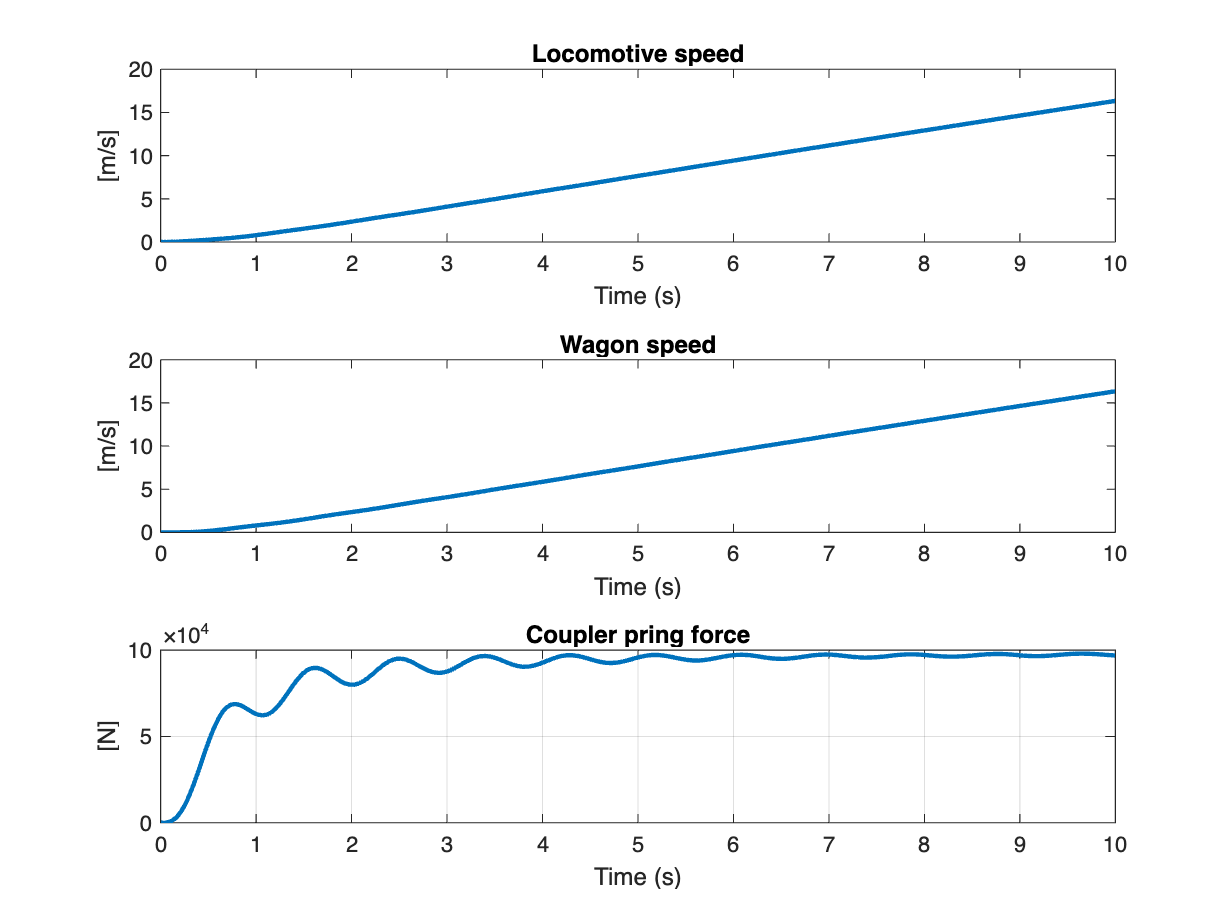

% call Runge Kutta integrator
[tSol, ySol] = ode45(@(t,x)ode_rhs(t,x), tspan, ics); % Solve the ODE using ode45

% Plot the results
figure;
tiledlayout(3,1)
nexttile
plot(tSol, ySol(:,2),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Locomotive speed');

nexttile
plot(tSol, ySol(:,3),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Wagon speed');

nexttile
plot(tSol, ySol(:,1),'LineWidth',2);
xlabel('Time (s)');
ylabel('[N]');
title('Coupler pring force');



grid on;